# Fluorescence emission spectra

% Author: Abbas El Moussawi
% COPYRIGHT 2024: EMPI-RF - University of Duisburg-Essen  
init;

**Species**

species = availableSpecies(1);


*     Add new species in .mat format under ".\LIFSim4.0\input-data\lines\" , *

*    see documentation section "Importing lines and partition function" for details*

**Laser parameters **

unit = '1/cm';
unit = lower(unit);
laserPosPlot = 44420;
checkWnum(unit,laserPosPlot);
laserPos = laserPosPlot;
dnuGLaser = 0.2;
dnuLLaser = 0.001;



**Detection parameters (spectrometer)**

startWnEm = 33333;
checkWnum(unit,startWnEm);
endWnEm = 46500;
checkWnum(unit,endWnEm);
stepEm = 1;
dnuGsm = 0.1;
dnuLsm = 0.005;


emWnum = startWnEm:stepEm:endWnEm;
plotWnum = emWnum;

if strcmpi(unit,'nm')
    emWnum = convWnumWlen(emWnum);
    dnuGsm = convWnumWlen(dnuGsm,endWnEm);
    dnuLsm = convWnumWlen(dnuLsm, endWnEm);
    dnuGLaser = convWnumWlen(dnuGLaser, laserPos);
    dnuLLaser = convWnumWlen(dnuLLaser, laserPos);
    laserPos = convWnumWlen(laserPos);
end

outside = (dnuGLaser+dnuLLaser)*3;
[linelist, Z, n, ~,MM, emList] = selectLines(species, laserPos,outside=outside);

**Detection filter**

    Keep empty to ignore filter

pathFilter = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\filters\sio.Notch.0deg.xlsx";
fileUnit = 'nm';
filter = 0;
nmFilter = 0;
if isfile(pathFilter)

    [filter, nmFilter] = loadSpectrum(pathFilter,fileUnit);
    [linelist,emList] = fluorTransm(linelist, emList, filter);
end


**Environment**

P = 2;
T = 1500;



**Collisions data**

dnuLex = 0.01;
dnuSh = 0;

colls =  collisions(species);

if ~isempty(colls)
    path = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\lifmat\input-data\gas-composition-example.xlsx";

     *(Support for NO, otherwise update function 'collissions')*

    gas = loadGasComposition(path);

    [dnuLex, dnuSh] = collisionalBroadening(gas, colls, P, T);
    [quen,linelist] = quenchRate(gas, colls, T, P, MM, linelist);

end



## Result plot

 

disp("Lines excited:")

Lines excited:


for i = 1:n
    pos = linelist{i}.nu0;
    if strcmpi(unit,'nm')
        pos = convWnumWlen(linelist{i}.nu0);
        uu = unit;
    else
        uu = 'cm⁻¹';
    end

    pos = num2str(pos);
    disp([ num2str(i) '. ' linelist{i}.branch ', position: ' pos ' ' uu]);
end

1. R12, position: 44420.1328 cm⁻¹
2. Q2, position: 44420.2227 cm⁻¹
3. Q1, position: 44420.7227 cm⁻¹
4. P21, position: 44420.8047 cm⁻¹
5. R2, position: 44420.8555 cm⁻¹



[fluorSpec, eT, sumFluor] = emissionSpec(...
    laserPos,...
    emWnum,...
    linelist,...
    MM, ...
    T,...
    emList,...
    dnuGL=dnuGLaser,...
    dnuLL=dnuLLaser,...
    dnuLex=dnuLex,...
    dnuL=dnuLex,...
    Z=Z ...
    );

if strcmpi(unit,'nm')
    fluorSpec = fliplr(fluorSpec);
    sumFluor = fliplr(sumFluor);
end


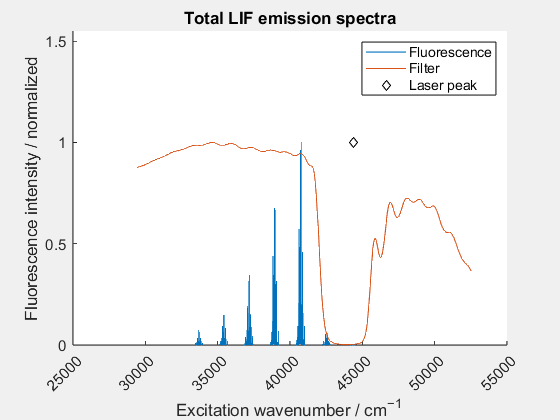

popout = true;
f = figure;
if popout
    set(gcf,'Visible','on');
end
hold on
plot(plotWnum, sumFluor, LineStyle="-",Marker="none", DisplayName='Fluorescence')
if istable(filter)
    if strcmpi(unit,'nm')
        plot(nmFilter.wnum, nmFilter.intens, LineStyle="-",Marker="none", DisplayName='Filter')
    else
        plot(filter.wnum, filter.intens, LineStyle="-",Marker="none", DisplayName='Filter')
    end
end
plot(laserPosPlot, 1, LineStyle="none",Marker="diamond", DisplayName='Laser peak', Color='Black')
LABELS(unit);
LABELS("flourIntNorm");
title('Total LIF emission spectra')
legend show
ylim([0 1.55])

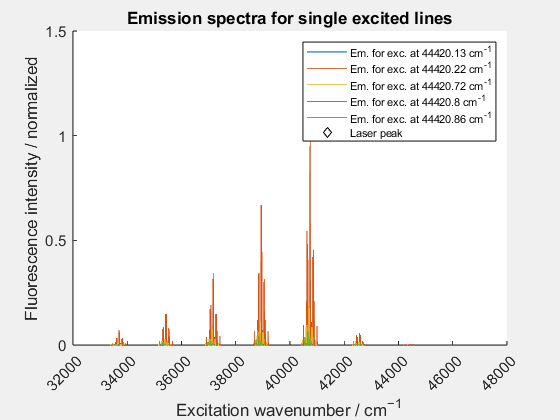


figure, hold on
if popout
    set(gcf,'Visible','on');
end
title('Emission spectra for single excited lines')

for i = 1:numel(eT)
    line = linelist{eT(i)};
    nu0 = line.nu0;
    nu0 = round(nu0,2);
    uu = 'cm^{-1}';

    if strcmpi(unit,'nm')
        nu0 = convWnumWlen(nu0);
        uu = 'nm';
        nu0 = round(nu0,4);
    end
    dispname = ['Em. for exc. at ' num2str(nu0) ' '  uu ];
    plot(plotWnum, fluorSpec(eT(i), :), LineStyle="-",Marker="none", DisplayName=dispname)
end


ylim([0 1.5])

LABELS(unit,true);
LABELS("flourIntNorm");
legend("FontSize", 8)

plot(laserPosPlot, 1, LineStyle="none",Marker="diamond", DisplayName='Laser peak', Color='Black')